## Problem 1 

% Set the parameters
%
q=1;
dt=0.1;
s=0.5;
m0=[0;0;1;-1];
P0=eye(4);
A=kron([1,dt;0,1],eye(2));
Q=q*kron([dt^3/3,dt^2/2;dt^2/2,dt],eye(2));
H=kron([1,0],eye(2));
R=s^2*eye(2);
X0=m0;           % true initial state

% Generate a track and measurements
%
nx=size(Q,1); ny=size(R,1);
nk=100;
X=zeros(nx,nk);
Y=zeros(ny,nk);
x=X0;
rng(33,'v5normal')   % use the legacy generator to replicate Figure 4.5
for k=1:nk
    x=mvnrnd(A*x,Q)';
    y=mvnrnd(H*x,R)';
    X(:,k)=x;
    Y(:,k)=y;
end



% RTS fixed-point smoother
%
m=m0; P=P0;
m_est = m0;

B = eye(length(m));
for k=1:nk % forward pass, Kalman filter (same as above)
    [mp,Pp]=kf_predict(m,P,A,Q);
    D=P*A';
    G=D/Pp;
    B = B*G;
    [m,P]=kf_update(mp,Pp,Y(:,k),H,R);
    
    %update estimation of initial state
    m_est = m_est + B*(m-mp);
end
m_est

m_est =     0.6466
    0.1286
    1.0342
   -1.3172


Problem 2:

clear all

%generate initial values
rng('default'); rng(0) % set the random number generator's starting value
g=9.81;        % gravity acceleration constant
qc=1;          % power spectral density of white noise excitation
r=0.1;         % measurement noise variance
x0=[1.5;0];    % initial state (radian angle and angular velocity)
DT=0.01;       % time step size
nk=500;        % number of steps
T=(1:nk)*DT;   % timestamps
X=zeros(1,nk); % preallocate
Y=NaN(1,nk);   % preallocate using not-a-number
m=5;           % number of time steps per measurement

%generate data
u=x0(1); v=x0(2);
for k=1:nk
    u=u+DT/2*v; 
    v=v-g*DT*sin(u)+randn*sqrt(qc*DT);
    u=u+DT/2*v;
    if ~rem(k,m)
        Y(k)=sin(u)+sqrt(r)*randn;
    end
    X(k)=u;
end

%estimate initial state by smoothing/filtering
m0=[1.6;0];    
P0=0.1*eye(2);
Q=qc*[DT^3/4, DT^2/2; DT^2/2, DT];   
R=r;
filtername={'EKF','EKF2'};
GA={@GaussApproxEKF,@GaussApproxEKF2};
nf=length(filtername);
M1f=zeros(nf,nk);
for jf=1:nf   % loop for different filters
    m=m0; P=P0;
    m_est = m0;
    B = eye(length(m));
    for k=1:nk   % filter
        [mp,Pp,Dp]=gf_predict(m,P,@pendulum_f_leapfrog,Q,GA{jf});
        G=Dp/Pp;
        B = B*G;
        [m,P]=gf_update(mp,Pp,Y(k),@pendulum_h,R,GA{jf});
        
        %update estimation of initial state
        m_est = m_est + B*(m-mp);
        
        M1f(jf,k)=m(1);
    end
    disp(['Estimation of initial state with filter ',filtername{jf},' is ' ,num2str(m_est')])
    rmse=sqrt(mean((X(1,:)-M1f(jf,:)).^2));
    disp(['RMS error for ' filtername{jf} ' is ' num2str(rmse)])
end

Estimation of initial state with filter EKF is 1.8264     0.13482


RMS error for EKF is 0.19205


Estimation of initial state with filter EKF2 is 1.8371     0.10013


RMS error for EKF2 is 0.16762


Problem 3:

clear all

%generate initial values
rng('default'); rng(0) % set the random number generator's starting value
g=9.81;        % gravity acceleration constant
qc=1;          % power spectral density of white noise excitation
r=0.1;         % measurement noise variance
x0=[1.5;0];    % initial state (radian angle and angular velocity)
DT=0.01;       % time step size
nk=500;        % number of steps
T=(1:nk)*DT;   % timestamps
X=zeros(1,nk); % preallocate
Y=NaN(1,nk);   % preallocate using not-a-number
m=5;           % number of time steps per measurement

%generate data
u=x0(1); v=x0(2);
for k=1:nk
    u=u+DT/2*v; 
    v=v-g*DT*sin(u)+randn*sqrt(qc*DT);
    u=u+DT/2*v;
    if ~rem(k,m)
        Y(k)=sin(u)+sqrt(r)*randn;
    end
    X(k)=u;
end


m0 = [1.6;0];       % slightly off from x0
P0 = 0.1*eye(2);
Q=qc*[DT^3/3 0;0 DT];   % slightly off, nonsingular for PS
%Q=qc*[DT^3/4, DT^2/2; DT^2/2, DT];
R=r;

N=1000;              % number of particles
nbs=4;              % number of PS backward simulations
M=zeros(3,nk);      % preallocate the array of estimated angles

% Particle filter
xx=mvnrnd(repmat(m0,1,N)',P0)';
xpf=zeros(length(m0),N,nk+1); xpf(:,:,1)=xx;
for k=1:nk
    xx=mvnrnd(pendulum_f_leapfrog(xx)',Q)';
    if ~isnan(Y(k))
        w=normpdf(pendulum_h(xx)',Y(k),sqrt(R))';
        w=w/sum(w);
        xx=xx(:,resamp(w));
    end
    xpf(:,:,k+1)=xx;
    M(2,k)=mean(xx(1,:));
end
    
rmse=sqrt(mean((X(1,:)-M(2,:)).^2));
disp(['RMS error for PF  is ',num2str(rmse)])

RMS error for PF  is 0.17792


    
% Backward-simulation particle smoother
xs=xpf(:,randi(N,1,nbs),nk+1);
for k=nk:-1:1
    for j=1:nbs
        w=mvnpdf(repmat(xs(:,j),1,N)',pendulum_f_leapfrog(xpf(:,:,k))',Q)';
        w=w/sum(w);
        [~,J]=histc(rand,[0;cumsum(w(:))]); % a sample from 1:N
        xs(:,j)=xpf(:,J,k);
    end
    M(3,k)=mean(xs(1,:),2);
end
    
rmse=sqrt(mean(([x0(1) X(1,:)]-[M(3,:) M(2,end)]).^2));
disp(['RMS error for PS  is ',num2str(rmse)])

RMS error for PS  is 0.13491


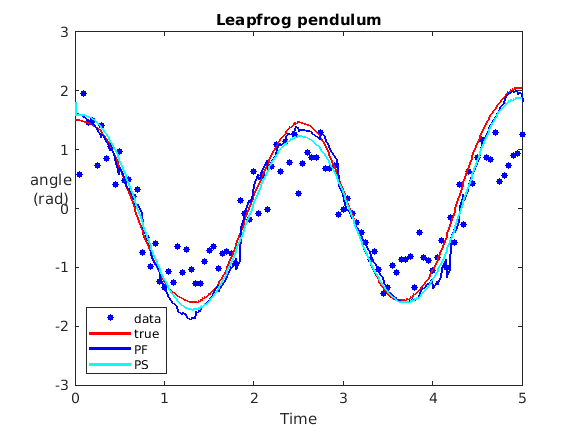


%plot results
figure,clf
plot(T,Y,'b.', ...
        [0,T],[x0(1),X(1,:)],'r-',...
        [0,T],[m0(1),M(2,:)],'b-',...
        [0,T],[ M(2,end) M(3,:) ],'c-',...
        'linewidth',2,'markersize',16);
    
title("Leapfrog pendulum")
axis([0 5 -3 3])
xlabel('Time')
ylabel({'angle';'(rad)'},'rot',0) 
legend('data','true','PF','PS','location','SW')

Problem 4:

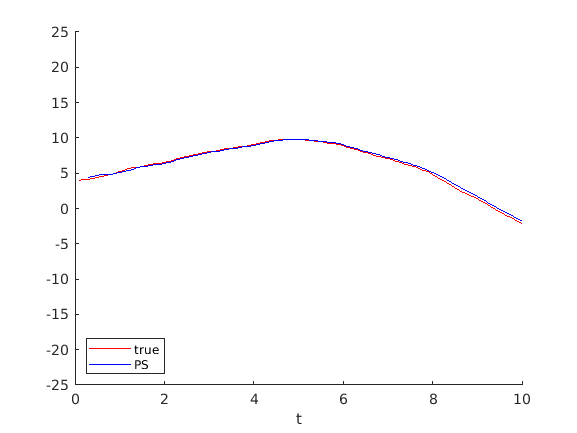



%Generate path
rng('default'); rng(0) 
DT=0.1; nk=100; Qc=1; r=0.1; x0=[4;0];
T=(1:nk)*DT; X=zeros(1,nk); Y=zeros(1,nk);
Ak=[1,DT;0,1]; Qk=Qc*[DT^3/3,DT^2/2;DT^2/2,DT];
x=x0;
for k=1:nk
    x=mvnrnd(Ak*x,Qk)'; X(k)=x(1);
    Y(k)=terrainnav_h(x)+sqrt(r)*randn;
end

%particle filter
m0=[4;0];
P0=diag([400,1]);  % large initial variance 
M=zeros(1,nk);     % preallocate filter mean
N=1000;            % number of particles
xx=mvnrnd(repmat(m0,1,N)',P0)';
xpf=zeros(length(m0),N,nk+1);
for k=1:nk
    xx=mvnrnd(tracking_f(xx)',Qk)';
    w=normpdf(terrainnav_h(xx)',Y(k),sqrt(r))';
    w=w/sum(w);
    xx=xx(:,resamp(w)); %resampling
    xpf(:,:,k+1)=xx;
    M(k)=mean(xx(1,:));
end

% Backward-simulation particle smoother
xs=xpf(:,randi(N,1,nbs),nk+1);
for k=nk:-1:3 %skip two first steps(k = 1,2 due to some problems)
    for j=1:nbs
        
        w=mvnpdf(repmat(xs(:,j),1,N)',tracking_f(xpf(:,:,k))',Q)';
        w=w/sum(w);
        [~,J]=histc(rand,[0;cumsum(w(:))]); % a sample from 1:N
        xs(:,j)=xpf(:,J,k);
    end
    M(3,k)=mean(xs(1,:),2);
end


plot(T,X,'r-',T(3:end),M(3,3:end),'b-')
axis([0 T(end) -25 25]), box off,  xlabel('t')
legend('true','PS','location','SW')

Problem 5

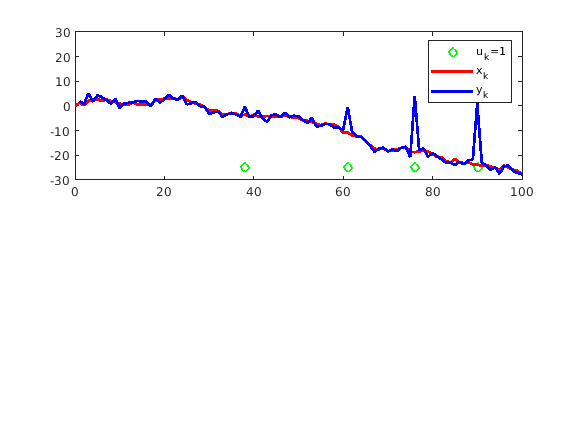

%Problem 5

clear all
% problem parameters
nk=100;             % number of time steps
up=[0.9,0.1];       % up(i) = Prob(u=i-1)
x0=[0 0]';               % initial value of state
A=[1 0.05; 0 1]; Q=[0.5 0;0 0.5];           % x_{k+1} ~ N(A*x_k,Q)
H={[1 0],[0 0]};R={1,100};  % y_k ~ N(H{u_k+1}*x_k,R{u_k+1})
m0=[0;0]; P0=zeros(2,2);          % x_0 ~ N(m0,P0)

% generate data and plot it
rng('default'); rng(0)
X=zeros(length(x0),nk); Y=zeros(1,nk); U=zeros(1,nk); % preallocate
x=x0;
for k=1:nk
    u=rand<up(2);    % sample from {0,1} with prob [up(1),up(2)]
    x=mvnrnd((A*x)',Q)';
    Y(k)=mvnrnd(H{u+1}*x,R{u+1});
    X(:,k)=x; U(k)=u;
end
figure(1), subplot(211)
kk=1:nk; Uis1=find(U==1); nUis1=length(Uis1);
plot(kk(Uis1),repmat(-25,1,nUis1),'go',...
    0:nk,[x0(1),X(1,:)],'r',1:nk,Y,'b','linewidth',2)
axis([0 nk -30 30])
legend('u_k=1','x_k','y_k')


% Particle filter
N=100;  % number of particles
nx=length(x0);
Mpf=zeros(nx,nk); w=zeros(1,N); % preallocate
xu=[mvnrnd(repmat(m0,1,N)',P0)'
    rand(1,N)<up(2)           ];
for k=1:nk
    % propagate particles
    u=rand(1,N)<up(2);
    xu(end,:)=u;
    for i=1:N
        xu(1:nx,i)=mvnrnd((A*xu(1:nx,i))',Q)';
    end
    % compute weights
    for i=1:N
        w(i)=normpdf(Y(k),(H{u(i)+1}*xu(1:nx,i))',sqrt(R{u(i)+1}))';
    end
    J=resamp(w/sum(w)); xu=xu(:,J);
    % posterior mean
    Mpf(:,k)=mean(xu(1:nx,:),2);
end
RMSEpf=sqrt(mean((X(1,:)-Mpf(1,:)).^2,2))

RMSEpf = 0.7544


% RB-Particle filter
Mrbpf=zeros(nx,nk);   % preallocate
m=repmat(m0,1,N);
P=zeros(nx,nx,N); for i=1:N, P(:,:,i)=P0; end
for k=1:nk
    u=rand(1,N)<up(2);
    for i=1:N
        [m(:,i),P(:,:,i)]=kf_predict(m(:,i),P(:,:,i),A,Q);
        RR=H{u(i)+1}*P(:,:,i)*H{u(i)+1}'+R{u(i)+1};
        w(i)=normpdf(Y(k),(H{u(i)+1}*m(:,i))',sqrt(RR));
    end
    J=resamp(w/sum(w)); u=u(J); m=m(:,J); P=P(:,:,J);
    for i=1:N
        [m(:,i),P(:,:,i)]=kf_update(m(:,i),P(:,:,i),Y(k),H{u(i)+1},R{u(i)+1});
    end
    Mrbpf(:,k)=mean(m,2);
end
RMSErbpf=sqrt(mean((X(1,:)-Mrbpf(1,:)).^2,2))

RMSErbpf = 0.7024

 Functions

 function [M,P] = kf_predict(M,P,A,Q)
    %updates kalman filter M and P.
    M = A*M;
    P = A*P*A'+Q;
end

function [M,P] = kf_update(M,P,Y,H,R)
    % updates M and P given old M, old P, data Y,H and R
    S = H*P*H' + R;
    K = P*H'*inv(S);
    M = M + K*[Y-H*M];
    P = P-K*S*K';
end

function [mu,S,C]=GaussApproxEKF(m,P,g,E)
[mu,Gx]=g(m);
C=P*Gx';
S=Gx*C+E;
end

function [mu,S,C]=GaussApproxEKF2(m,P,g,E)
[mu,Gx,Gxx]=g(m);
C=P*Gx';
S=Gx*C+E;
n=size(E,1);
for i=1:n
    mu(i)=mu(i)+0.5*trace(Gxx{i}*P);
    for j=1:n
        S(i,j)=S(i,j)+0.5*trace(Gxx{i}*P*Gxx{j}*P);
    end
end
end

function [m,P]=gf_update(m,P,y,h,R,GaussApprox)
if ~isnan(y)
    [mu,S,C]=GaussApprox(m,P,h,R);
    K=C/S;
    P=P-K*S*K';
    m=m+K*(y-mu);
end
end

function [m,P,D]=gf_predict(m,P,f,Q,GaussApprox)
[m,P,D]=GaussApprox(m,P,f,Q);
end

Functions for problem 2

function [f,Fx,Fxx]=pendulum_f_leapfrog(x)
DT=0.01; g=9.81;
A = [1 DT;0 1];
f = A*x - [DT/2; 1]*g*DT*sin(x(1)+DT/2*x(2));
Fx = A - [DT/2,DT^2/4;1,DT/2]*g*DT*cos(x(1)+DT/2*x(2));
Fxx{2} = g*DT*sin(x(1)+DT/2*x(2))*[1,DT/2;DT/2,DT^2/4];
Fxx{1} = Fxx{2}*DT/2;
end

function [h,Hx,Hxx]=pendulum_h(x)   % same as pendulum_demo
h=sin(x(1,:));
Hx=[cos(x(1)) 0];
Hxx{1}=[-sin(x(1)) 0
         0          0];
end

Function for problem 3

function J=resamp(W)
[~,J]=histc(rand(length(W),1),[0;cumsum(W(:))]);
end

Functions for problem 4

function hval = terrainnav_h(X)
x = X(1,:);
hval = 100+50*sin(x/7)+20*sin(x/5)+20*cos(x/4)+10*sin(x);
end

function fval=tracking_f(x)
DT = 0.1;
fval = [1 DT; 0 1]*x;
end

function hval=tracking_h(x)
hval = sqrt((0.5-x(1,:)).^2+0.01);
end